% Compatible image formats are:
% XWD, TIFF, RAS, PPM, PNG, PGM, PCX, JP2, JPEG, ICO, HDF4, GIF, CUR, BMP

% Load your PNG or other compatible lossless source here
ref = imread('E:\jacks matlabs\Lenna.png');
% Use the same file path here
refinfo = dir('E:\jacks matlabs\Lenna.png');
refsize = refinfo.bytes;

% Load your compressed image here (It's easier to convert to tif for this)
comp = imread('E:\jacks matlabs\Lenna.avif.tif');
% Load the unconverted compressed image here
compinfo = dir('E:\jacks matlabs\Lenna.avif');
compsize = compinfo.bytes;
compname = compinfo.name;
diffsize = refsize - compsize;

% This just initializes some variables or some shit
[ssimval, ssimmap] = ssim(comp,ref);
[peaksnr, snr] = psnr(comp, ref);
err = immse(comp, ref);

% Commenting out these plot things just looks nicer
%subplot(1,2,1); 
fprintf('Results for: %s', compname);

Results for: Lenna.avif

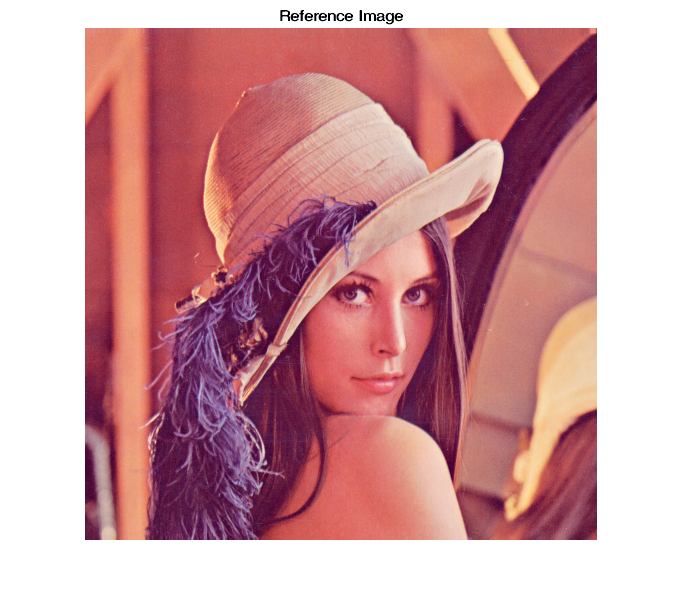

imshow(ref); title('Reference Image');

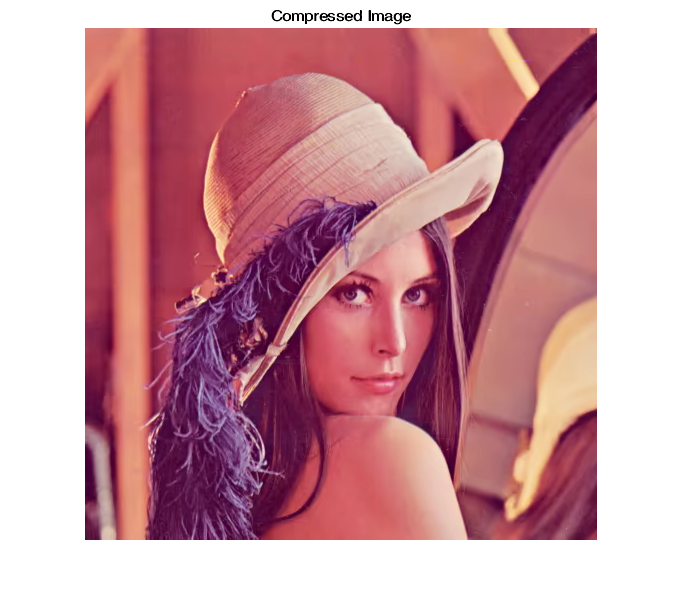

%subplot(1,2,2); 
imshow(comp); title('Compressed Image');

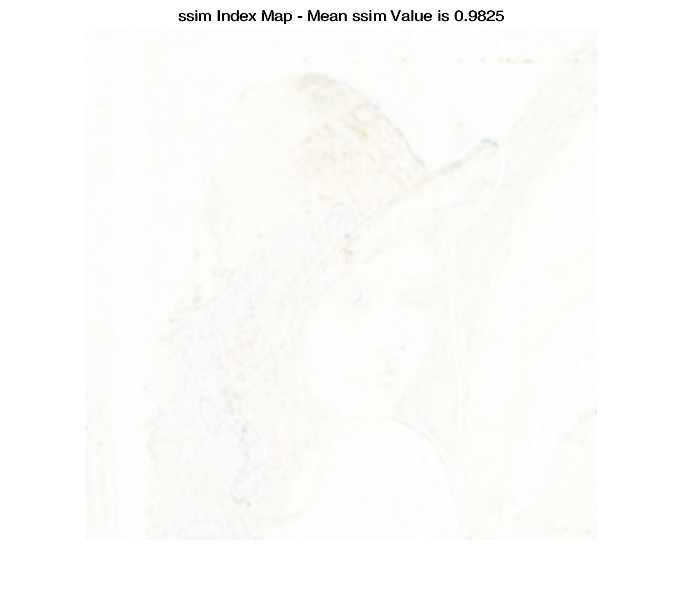

% This is the SSIM difference picture
figure, imshow(ssimmap,[]); title(sprintf('ssim Index Map - Mean ssim Value is %0.4f',ssimval));

% Results and math and shit
fprintf('┌-----------------------┬-------------------------------┐');

┌-----------------------┬-------------------------------┐

fprintf('| The Peak-SNR value is:|     %0.4fdB Higher is better|', peaksnr);

| The Peak-SNR value is:|     29.2198dB Higher is better|

fprintf('├-----------------------┼-------------------------------┤');

├-----------------------┼-------------------------------┤

fprintf('| The SNR value is:     |     %0.4fdB Higher is better|', snr);

| The SNR value is:     |     24.0823dB Higher is better|

fprintf('├-----------------------┼-------------------------------┤');

├-----------------------┼-------------------------------┤

fprintf('| The SSIM value is:    |      %0.4f   Higher is better|',ssimval);

| The SSIM value is:    |      0.9825   Higher is better|

fprintf('├-----------------------┼-------------------------------┤');

├-----------------------┼-------------------------------┤

fprintf('| The MSE value is:     |     %0.4f    Lower Is Better|',err);

| The MSE value is:     |     77.8209    Lower Is Better|

fprintf('├-----------------------┼-------------------------------┤');

├-----------------------┼-------------------------------┤

fprintf('| Original File Size:   |                   %4.0f bytes|',refsize);

| Original File Size:   |                   472834 bytes|

fprintf('├-----------------------┼-------------------------------┤');

├-----------------------┼-------------------------------┤

fprintf('| Compressed File Size: |                    %4.0f bytes|',compsize);

| Compressed File Size: |                    17815 bytes|

fprintf('├-----------------------┼-------------------------------┤');

├-----------------------┼-------------------------------┤

fprintf('| Size Difference:      |                   %4.0f bytes|',diffsize);

| Size Difference:      |                   455019 bytes|

fprintf('└-----------------------┴-------------------------------┘');

└-----------------------┴-------------------------------┘